### `Mapping Delivery Locations and Restaurant on a Geographical Map`

`1. Data Preparation`

% Delivery locations data
delivery_lat = [13.015377, 12.944179, 13.019096, 13.018453, 13.044179, 12.984179, 12.994365, 12.989934, 13.005662, 13.063298, 13.069496, 13.009496, 13.009096, 12.923041, 12.995662, 12.984365, 13.063284, 13.059166, 12.993284, 13.079198, 13.058453, 12.936229, 13.009496, 13.049198, 13.013298, 13.068453, 13.015662, 12.999496, 12.990324, 13.065662, 13.050221, 12.992161];
delivery_lon = [77.736664, 77.625797, 77.680625, 77.683685, 77.725797, 77.665797, 77.676155, 77.739386, 77.68413, 77.744293, 77.755999, 77.695999, 77.670625, 77.693237, 77.67413, 77.666155, 77.745428, 77.720709, 77.675428, 77.620997, 77.723685, 77.626791, 77.695999, 77.590997, 77.694293, 77.733685, 77.69413, 77.685999, 77.665748, 77.74413, 77.725396, 77.616014];

% Restaurant location
restaurant_lat = 12.94993;
restaurant_lon = 77.69939;

`2. Create a figure, Plot Delivery and Restaurant Locations, and Customize Plot`

% Create a figure
figure;

% Plot delivery locations
geoplot(delivery_lat, delivery_lon, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;

% Plot restaurant location
geoplot(restaurant_lat, restaurant_lon, 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

% Customize the plot
title('Bangalore Delivery Locations and the Restaurant');
legend('Delivery Locations', 'Restaurant', 'Location', 'best');
grid on;

`3. Set Geographical Limits and Save Figure`

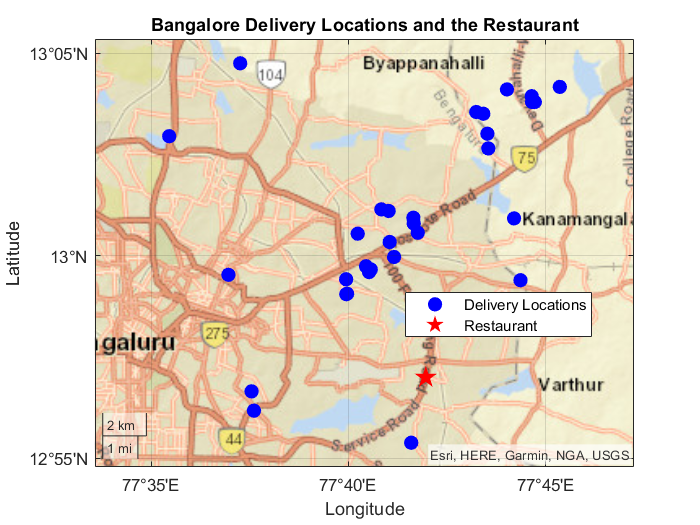

% Set geographical limits (optional)
geolimits([min([delivery_lat, restaurant_lat])-0.01 max([delivery_lat, restaurant_lat])+0.01], ...
          [min([delivery_lon, restaurant_lon])-0.01 max([delivery_lon, restaurant_lon])+0.01]);

% Display the map with the streets basemap
geobasemap('streets');

% Save the figure as an image
saveas(gcf, 'Bangalore.png');